% PLOT INDIVIDUAL TRIAL's Global Signal and 3 roi's waves - for manual
% rejection

% to avoid problems, open matlab in the terminal as:...
% ' ./matlab -softwareopengl'

clear
W = pwd;
cd '/home/tamara/Documents/MATLAB/VSDI/TORus'
user_settings
cd(W)

%----------------------------------------------------------------
% @SET: fish + configuration
%----------------------------------------------------------------
% 
% nfish = 18;
% cond_codes = [501]; % DO NOT INCLUDE THE BLANK CONDITION (or the threshold will fail)
% ATT: the threshold will be computed respect to the maxim um condition


% for rowi = [1:2]
% clearvars -except grouptiles rowi path
% TO LOOP FROM STRUCTURE
...................................
% load('/home/tamara/Documents/MATLAB/VSDI/TORus/plot/informes/05_figure_definit/grouptiles_all.mat')
% load('/home/tamara/Documents/MATLAB/VSDI/TORus/plot/informes/05_figure_definit/grouptiles_all.mat')
% 
% nfish = grouptiles{rowi,1};
% cond_codes = grouptiles{rowi,2};
% selroinames = grouptiles{rowi,3};
% refroiname = grouptiles{rowi,4};
% ....................................


% TO SKIP THE LOOP
% ....................................
nfish =10;
cond_codes = [1000:1003];
selroinames = {'dm4m_R2',  'dm2_R2' ,'dldm_R'};%dm3 ORIGINAL

% ....................................


movie_ref = '_18filt6'; % input movie '_17filt5'
% movie_ref = '_17filt5'; % input movie '_17filt5'
% movie_ref = '_15filt5'; % usado para 220608


% savein = '/home/tamara/Documents/MATLAB/VSDI/TORus/plot/informes/03_figure_sketch/def_figs/tiles/'; %
savein = '/home/tamara/Documents/MATLAB/VSDI/TORus/plot/informes/05_figure_definit/'; %
% 
% % FOR TILES AND EARLY-PEAK FRAMES
% %---------------------------------------------------------------
% fact_thresh = 0.4; % @SET : limits parameters
% fact_clim= 1.5;
% 
% thresh_mode = 'wavebased_thresh_max'; % 'moviebased_thresh_max' 'wavebased_thresh_max' 'wavebased_thresh_local' 'manual'. 'moviebased_thresh_max' is the one we have been using for tiles
% timerange_mode = 'auto_localwave' ; %'auto_localwave', 'manual', 'auto_fixed', 'auto_fixed75%%'
% 
% % auto_localwave - sets the timerange according to the condition's
% % reference wave 
% 
% % auto_fixed - when there several conditions, it calculates the reference wave of
% % all conditions, takes the highest wave to get the time limits and use that range for all conditions 
% 


% FOR WAVES
%---------------------------------------------------------------
% Note that for the computation initial and ending times from tiles and
% early peaks, the dF movie is always used 
wave_units = 'dF'; % 'dF' '%F'
draw_thresh = 1;

% MANUAL PARAMETERS (if 'manual' options are selected)
%---------------------------------------------------------------

% if thresh_mode = 'manual' SET:
manual.clims = [];
manual.thresh = [];

% if timerange_mode = 'manual' SET:
manual.start_ms = [];
manual.end_ms = [];

%----------------------------------------------------------------
% @SET: MEASURE (OR LOOP THROUGH ALL MEASURES)
%----------------------------------------------------------------
reject_on= 3; %only to indicate whether it's rejected when plotting

setting.manual_reject = 1; %
setting.GSmethod_reject = 1;  %
setting.GSabsthres_reject = 0; %
setting.forcein = 0; %


% NEWMAP 1: from jet
%     n = 512;
%     bigjet = jet(n);
%     cmap_tile = bigjet(round(n*0.3):end, :);


% NEWMAP 2: from new function

% cmap_tile = colormap_loadBV4(256);
cmap_tile = colormap_loadBV2(256);
%     cmap_tile = colormap_loadBV();


%% LOAD AND SETTINGS
%----------------------------------------------------------------
% LOAD DATA
%----------------------------------------------------------------
VSDI = TORus ('load', nfish);

TORus_210509_loaded


VSDmov = TORus('loadmovie',nfish,movie_ref);

TORusMov_210509_18filt6.mat_loaded



% SELECT RECTANGULAR ROI TO CROP MOVIE
%----------------------------------------------------------------

selroi =name2idx(selroinames, VSDI.roi.labels_circ);
roilabels = VSDI.roi.labels_circ;
masks =  VSDI.roi.circle.mask;


%----------------------------------------------------------------
% COMPUTE REJECTION IDX FROM REJECT-OPTIONS
%----------------------------------------------------------------

rejectidx  = compute_rejectidx(VSDI, reject_on, setting);

"bradyvisual" rejection criteria is not considered


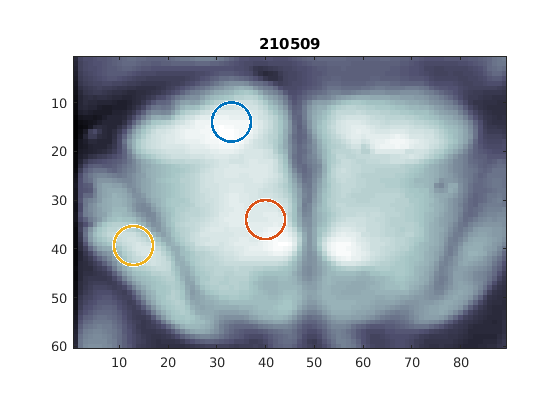


%----------------------------------------------------------------
% PEAK-FINDING FUNCTION PARAMETERS (to center the early-peak function)
%----------------------------------------------------------------

feedf.window.min = [-100 100]; %'feed-function' structure
feedf.window.max = [0 1200]; % where to find the max peak
feedf.window.movsum = 50; %ms
feedf.window.basel = [-25 0]; %cambiar a  -100
feedf.window.slope=50;
feedf.window.wmean=[0 350];

feedf.method = 'movsum';
%% ----------------------------------------------------------------
% CODE
%----------------------------------------------------------------
%----------------------------------------------------------------
% PRELIMINARY LOOP TO GET PARAMETERS
%----------------------------------------------------------------
%----------------------------------------------------------------

% fact_thresh = 0.4;

% -------------------------------------------------------
% GET REFERENCE-ROI MASK ----UNUSED
% -------------------------------------------------------

% idxDm4 =name2idx( ref_croproi, roilabels);
% ref_roimask = masks(:,:,idxDm4);

%%
            % ...................................................
            % PLOT BACKGROUND WITH ROI PREVIEW
            % ...................................................
            back = VSDI.backgr(:,:,VSDI.nonanidx(1));
            centers = VSDI.roi.circle.center(selroi, :) ;
            roicirc_preview_multiple_cmap(back, centers, VSDI.roi.circle.R, [], lines);
            title(num2str(VSDI.ref))

CONDITION1000


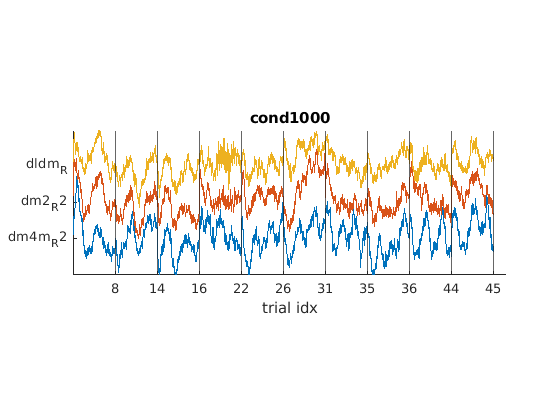

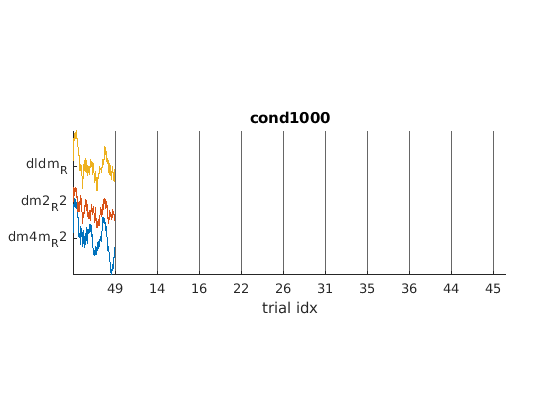

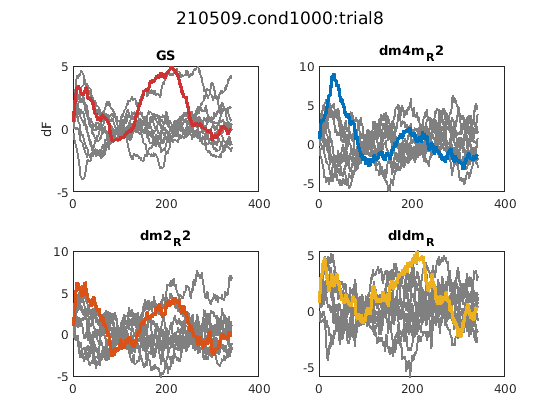

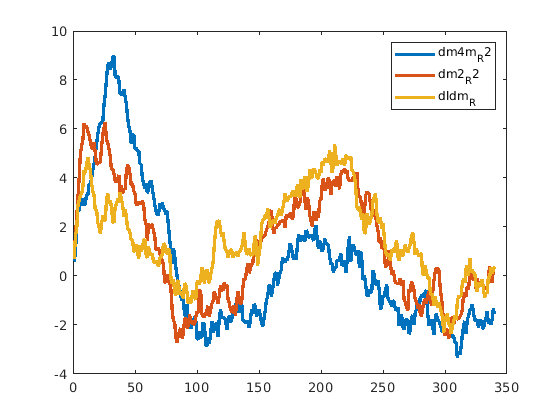

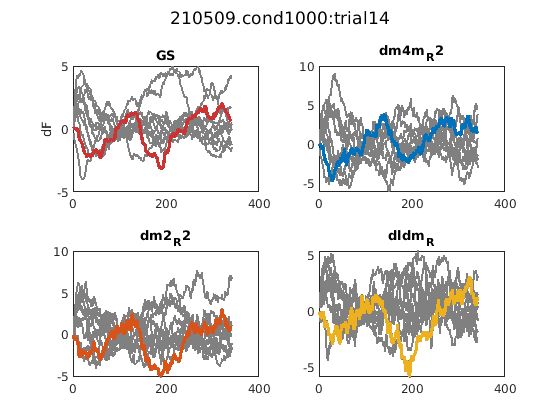

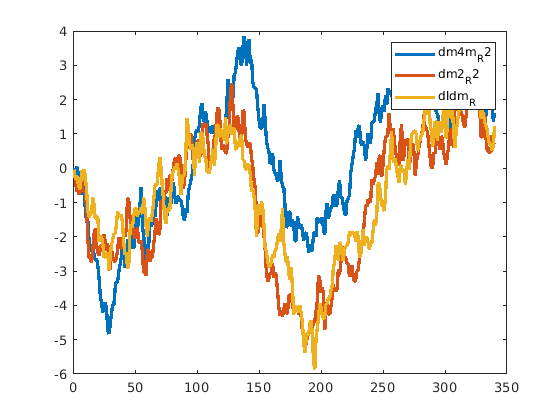

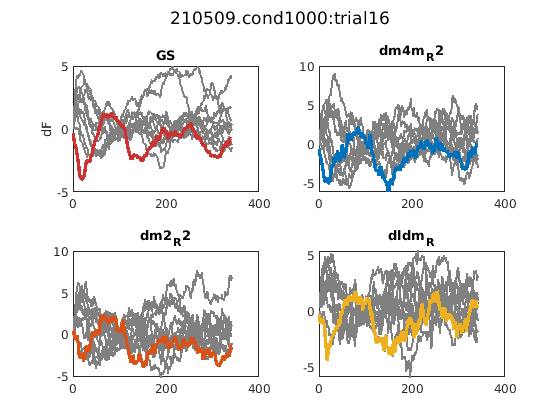

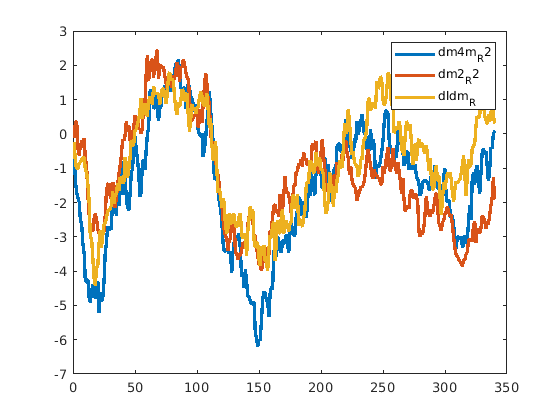

CONDITION1001


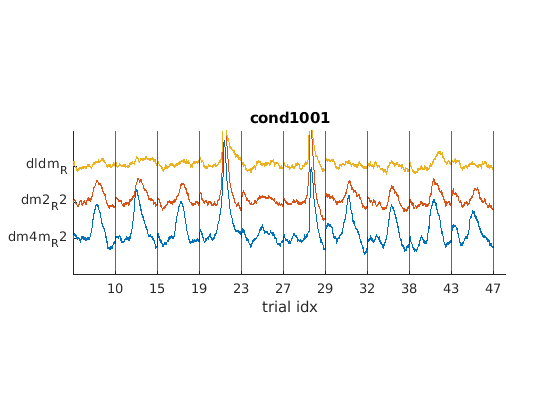

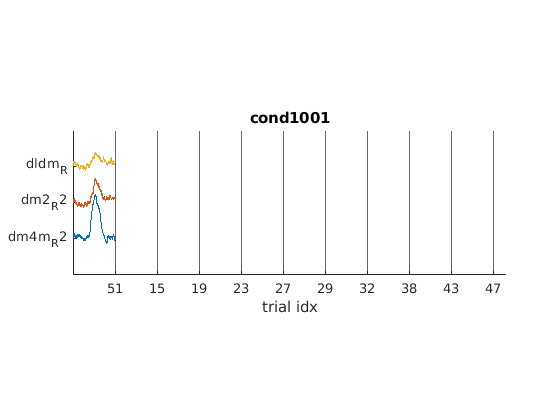

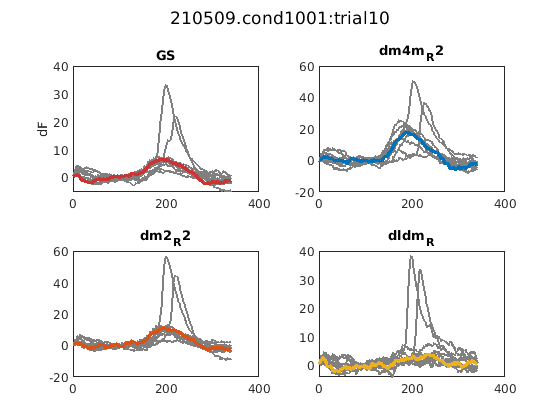

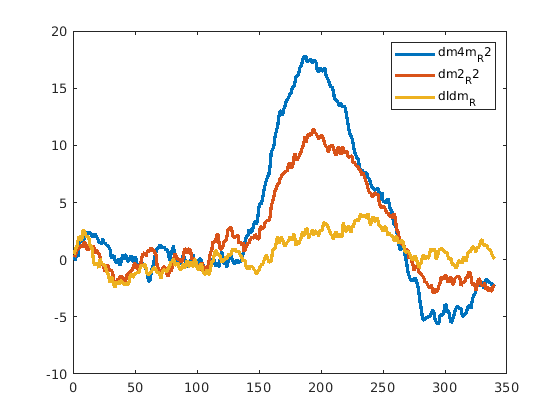

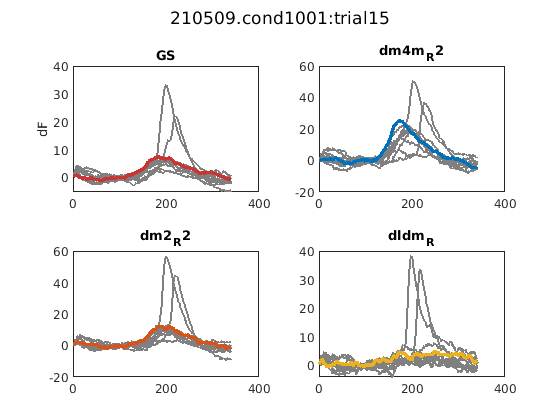

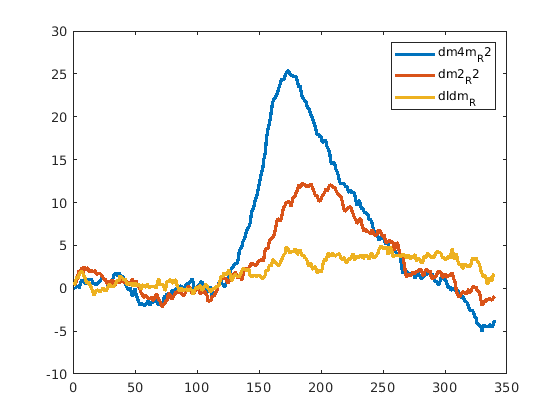

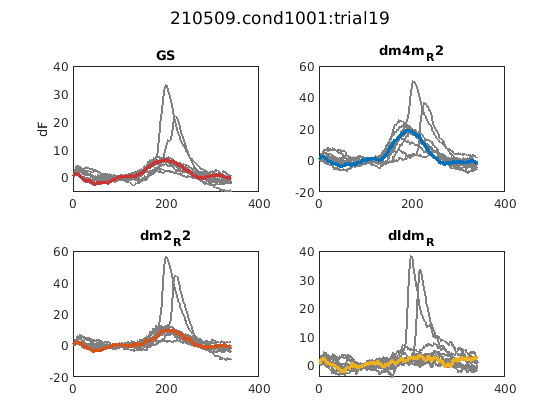

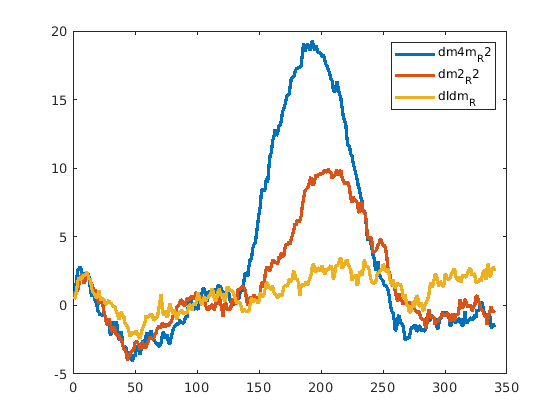

CONDITION1002


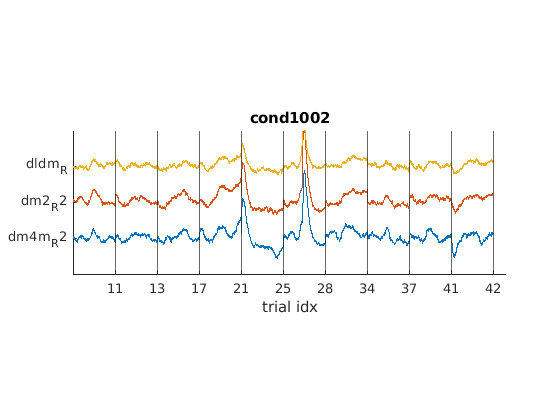

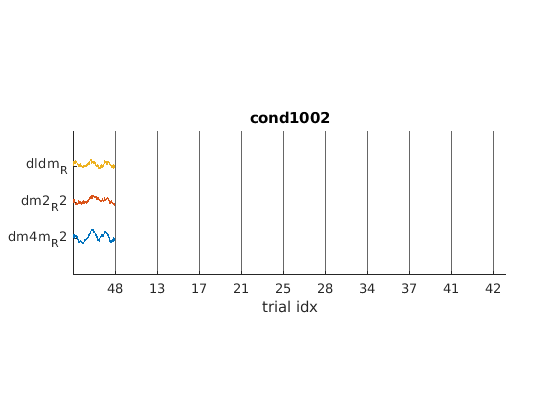

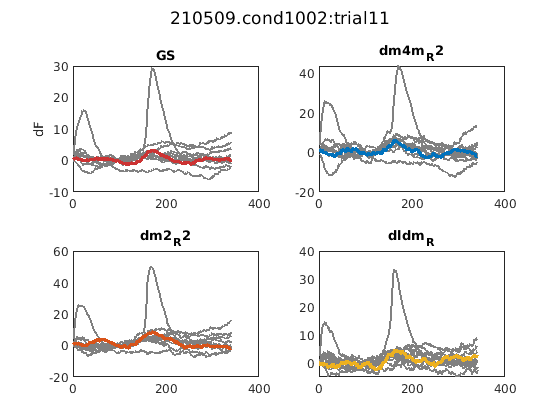

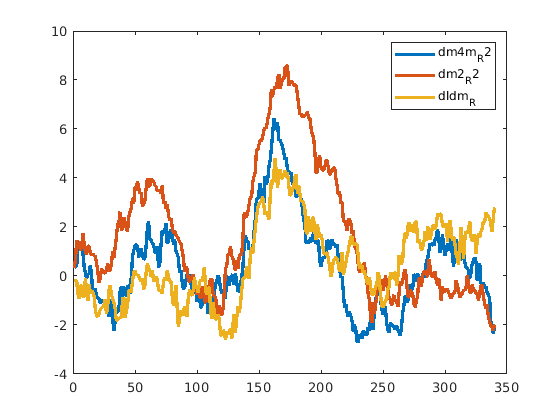

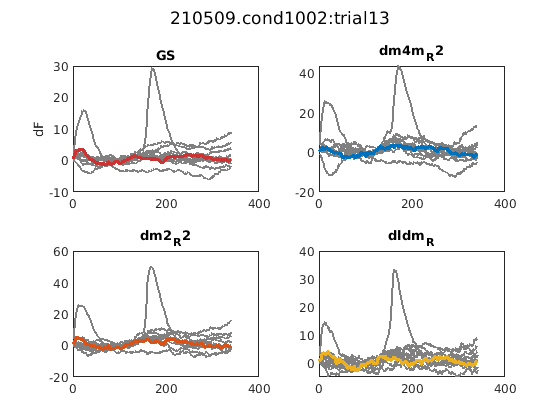

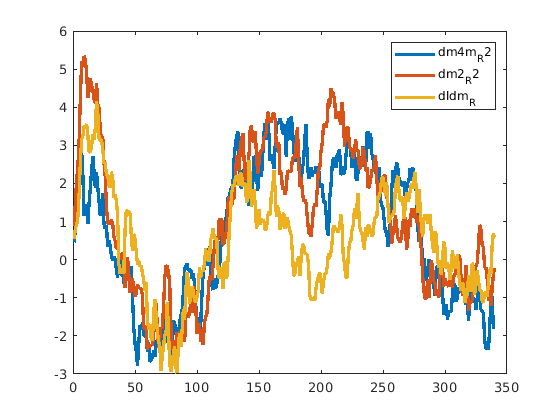

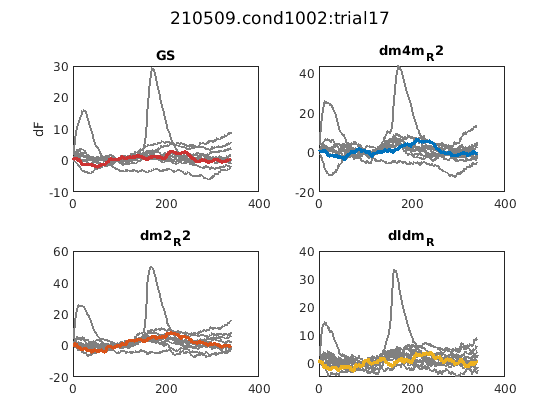

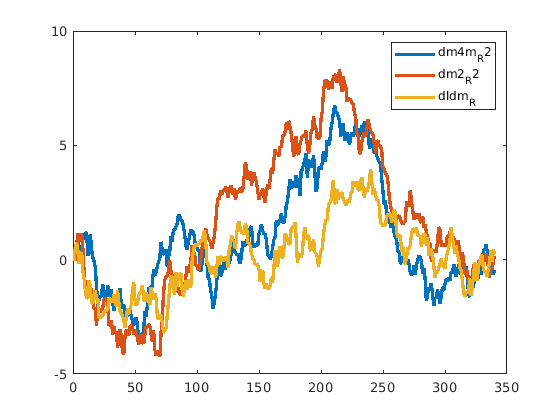

CONDITION1003


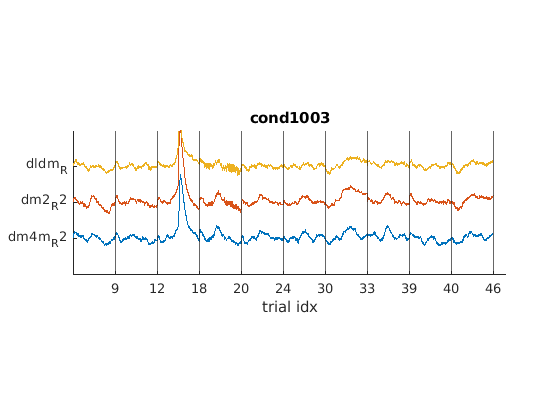

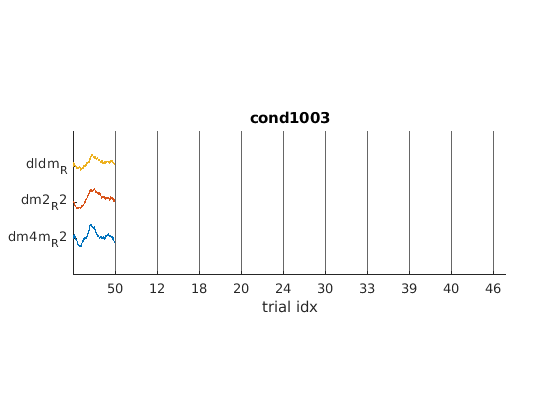

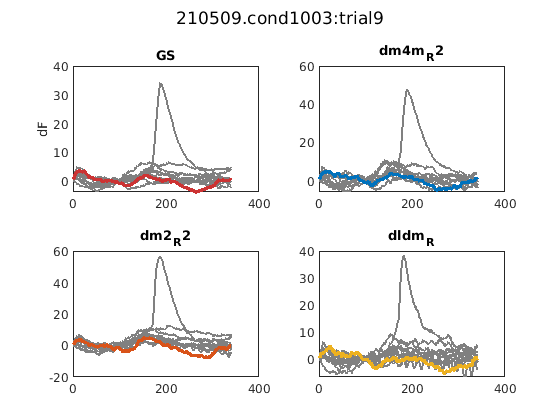

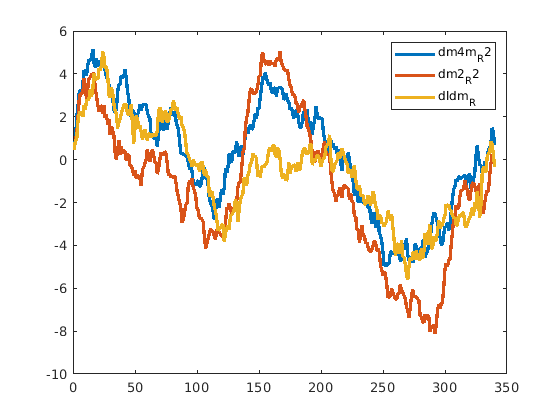

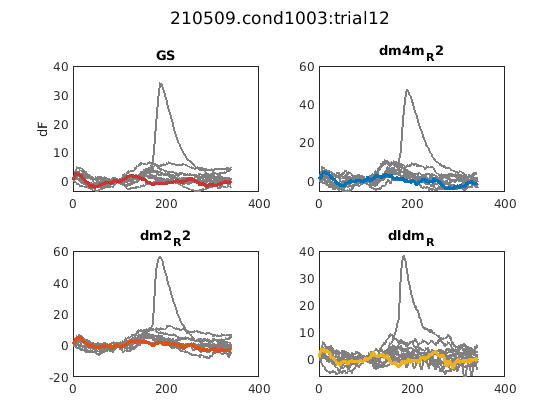

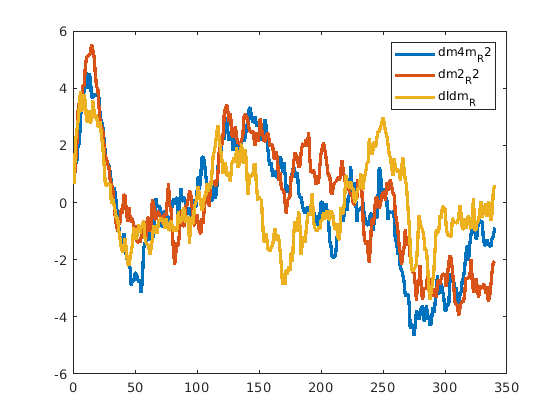

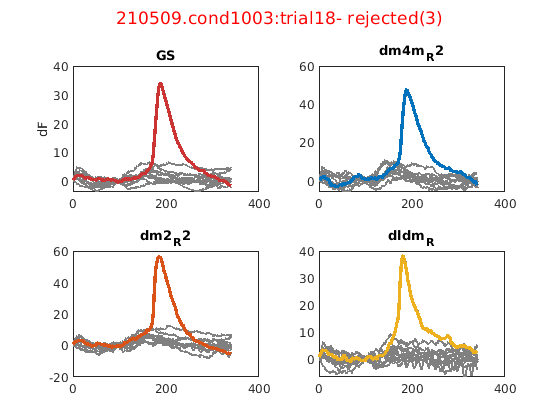

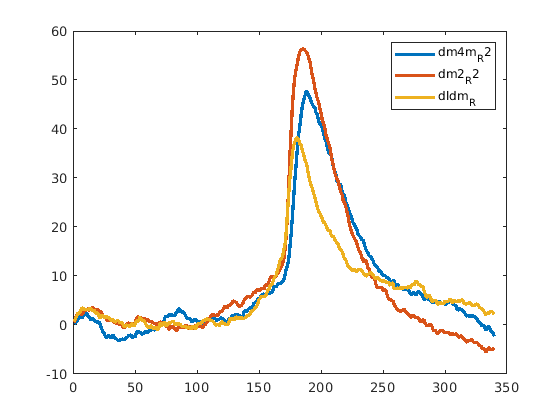


%-------------------------------------------------------------------
% LOOP THROUGH ALL CONDITIONS 
%-------------------------------------------------------------------

        ci = 0;
        for condi = makeRow(cond_codes)
            disp (['CONDITION' num2str(condi)])
            ci = ci+1;
            
            [sel_trials] = find(VSDI.condition(:,1)==condi);
            
%             if reject_on
%                 sel_trials = setdiff(sel_trials, rejectidx);
%             end
            
            
            % GET ALL WAVES: ATT - 'waves' DOES NOT RESPECT THE ROI IDX
            % ...................................................
            for triali= makeRow(sel_trials)
                tempmov = VSDmov.data(:,:,:,triali);
                GS(:,triali) = roi_TSave(tempmov,VSDI.crop.mask);

                i = 0; 
                for roii = makeRow(selroi)
                    i = i+1;
                    roimask = masks(:,:,roii);
                    waves(:,i, triali) = roi_TSave(tempmov,roimask);
                end
            end
            
            selnames = roilabels(selroi); %for waves
            
            
            % ...................................................
            % PLOT WAVEPLOT
            % ...................................................
            ratio = [3, 1, 1];
            plot_wavesplot2(waves, selnames, ['cond' num2str(condi)], sel_trials, 10, ratio)
            
            % Save and close
            
%             save_currentfig(path2save, name2save)

            % ...................................................
            % PLOT EACH TRIAL's GS WAVE AND ROI WAVES against all the rest
            % ...................................................
            for triali= makeRow(sel_trials)
                
                figure
                if ismember(triali, rejectidx)
                                    sgtitle([num2str(VSDI.ref) '.cond' num2str(condi) ':trial' num2str(triali) '- rejected(' num2str(reject_on) ')' ], 'Color', 'r')
                else
                                    sgtitle([num2str(VSDI.ref) '.cond' num2str(condi) ':trial' num2str(triali) ])
                end
                
                subplot(2,2,1)
                plot(GS(:,sel_trials), 'color', [.5 .5 .5], 'linewidth', 1.5)
                hold on;
                plot(GS(:,triali), 'color', [ .8 .2 .2], 'linewidth', 2.5)
                ylabel(wave_units);
                title('GS')
                
                % PLOT EACH REGION'S 
                f = 2; map= lines;
                for i = 1:length(selnames)
                    subplot(2,2,f)
                    plot(squeeze(waves(:,i,sel_trials)), 'color', [.5 .5 .5], 'linewidth', 1.5)
                    hold on;
                    plot(squeeze(waves(:,i,triali)), 'color', map(i,:), 'linewidth', 2.5)
                    title(selnames{i})
                    f = f+1;
                end
                
            % ...................................................
            % PLOT EACH TRIAL's ROI WAVES TOGETHER
            % ...................................................
                figure
                for i = 1:length(selnames)
                    plot(squeeze(waves(:,i,triali)), 'color', map(i,:), 'linewidth', 2.5, 'displayname', selnames{i})
                    hold on
                end
                hold off
                legend

                
            end
            
        end

        blob()